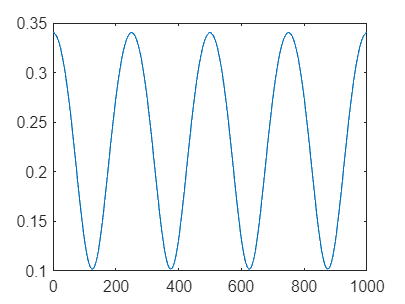

clear
clc
lambda = 400:700;   %光的波长
n = 1.4;        %硅片折射率
n0 = 1;         %空气折射率
ng = 3.8;       %硅片折射率
i = 0;          %折射角
x = 1:1000;      %薄膜厚度
delta = 4*pi*n*x*cos(i)/lambda;
R = (n^2*(n0-ng)^2*cos(delta/2).^2+(n^2-n0*ng)^2*sin(delta/2).^2)./...
    (n^2*(n0+ng)^2*cos(delta/2).^2+(n^2+n0*ng)^2*sin(delta/2).^2);
plot(R)